# **TU: K-Nearest Neighbors**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Classification with kNN

**Gyeonheal An**

**21900416**

## Example: Classification Using Nearest Neighbors

**Distance Metrics**

Use [`pdist2`](https://kr.mathworks.com/help/stats/pdist2.html) to find the distance between a set of data and query points.

- Euclidean distance

- Standardized Euclidean distance

- Mahalanobis distance

- Cosine distance

***k*****-Nearest Neighbor Search and Radius Search**

- **Exhaustive Search(default)**

- **Kd-Tree (feature <10)**

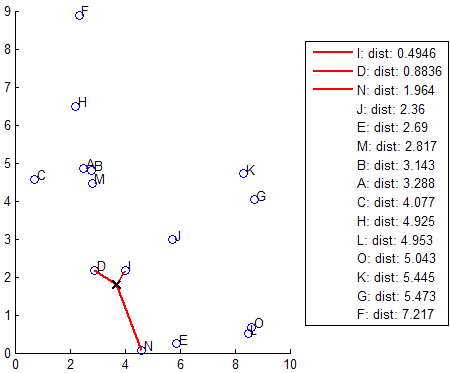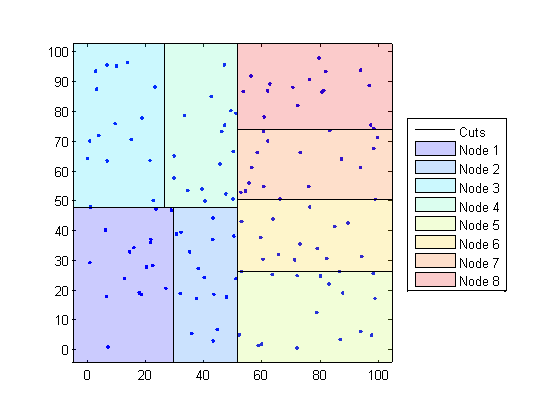

Randomly generate normally distributed data into two matrices. The number of rows can vary, but the number of columns must be equal. This example uses 2-D data for plotting.

rng(1) % For reproducibility

% Input Data
X = randn(50,2);

% Query
Y = randn(4,2);

h = zeros(3,1);
figure
h(1) = plot(X(:,1),X(:,2),'bx');
hold on
h(2) = plot(Y(:,1),Y(:,2),'rs','MarkerSize',10);
title('Heterogeneous Data')

**Mahalanobis distance**

Find the indices of the three nearest observations in `X` to each observation in `Y`.

k = 3;
[Idx,D] = knnsearch(X,Y,'Distance','mahalanobis','k',k);

`idx` and `D` are 4-by-3 matrices.

- `idx(j,1)` is the row index of the closest observation in `X` to observation *j* of `Y`, and `D(j,1)` is their distance.

- `idx(j,2)` is the row index of the next closest observation in `X` to observation *j* of `Y`, and `D(j,2)` is their distance.

- And so on.

Identify the nearest observations in the plot.

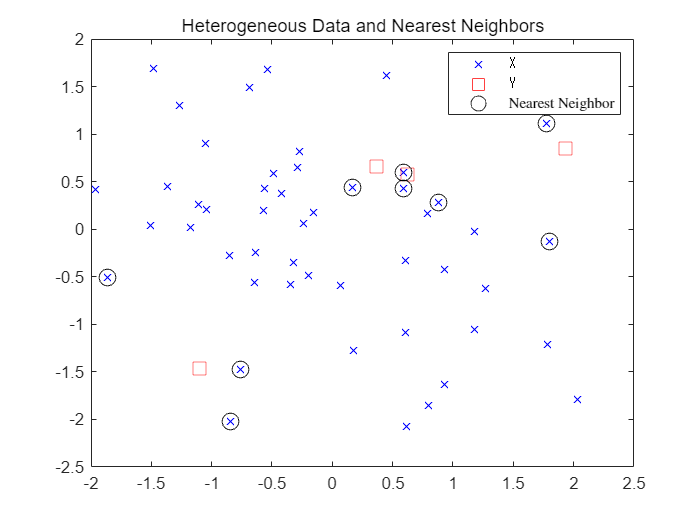

for j = 1:k
    h(3) = plot(X(Idx(:,j),1),X(Idx(:,j),2),'ko','MarkerSize',10);
end 
legend(h,{'\texttt{X}','\texttt{Y}','Nearest Neighbor'},'Interpreter','latex')
title('Heterogeneous Data and Nearest Neighbors')
hold off

# Exercise  

## Exercise : K-NN Classification with CWRU

### Dataset :  CWRU dataset features

- Given dataset contains many features extracted from CWRU dataset

- We will select 2~3 features for exercise

- Normal,  Outer and Inner Race Fault

clear

%% Train
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_train.mat");

feature1 = "sv";                % skewness value of time data
feature2 = "ipf";               % impulse factor
X(:, 1) = table2array(glob_all_train(:, feature1));
X(:, 2) = table2array(glob_all_train(:, feature2));
Y = class_cwru_train;       % fault class
N = size(X,1);
tbl=table(X(:, 1),X(:, 2),Y);



%% Test
load("../../Dataset/CWRU_selected_dataset/Feature_data/sample_test.mat");

Xtest(:, 1) = table2array(glob_all_test(:, feature1));
Xtest(:, 2) = table2array(glob_all_test(:, feature2));
Ytest = class_cwru_test;                                 
Ntest=size(Xtest,1);
tblTest=table(Xtest(:, 1),Xtest(:, 2),Ytest);



#### Plot Test Data

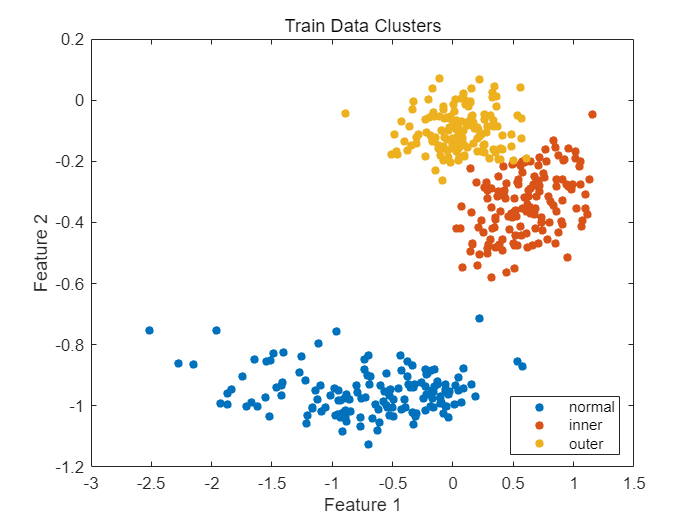

figure
gscatter(X(:,1),X(:,2),Y)
title('Train Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### KNN Train

Construct the classifier using `fitcknn`.

rng(10); % For reproducibility

Mdl = fitcknn(X,Y)

Mdl =   ClassificationKNN
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'inner'  'normal'  'outer'}
           ScoreTransform: 'none'
          NumObservations: 432
                 Distance: 'euclidean'
             NumNeighbors: 1


  Properties, Methods


#### Training loss (all train set)

Examine the resubstitution loss, which, by default, is the fraction of misclassifications from the predictions of `Mdl`. (For nondefault cost, weights, or priors, see [loss](docid:stats_ug.bs85nh7).).

%%% YOUR CODE GOES HERE
mlResubErr = resubLoss(Mdl)

mlResubErr = 0

The classifier predicts incorrectly for 4% of the training data.

#### Cross-validation (k-fold)

Construct a cross-validated classifier from the model.

%%% YOUR CODE GOES HERE
cp = cvpartition(Y,'KFold',10)  %k-fold

cp = K-겹 교차 검증 분할
   NumObservations: 432
       NumTestSets: 10
         TrainSize: 389  388  388  389  389  389  389  389  389  389
          TestSize: 43  44  44  43  43  43  43  43  43  43
          IsCustom: 0

Examine the cross-validation loss, which is the average loss of each cross-validation model when predicting on data that is not used for training.

%%% YOUR CODE GOES HERE
cvml = crossval(Mdl,'CVPartition',cp);
mlCVErr = kfoldLoss(cvml)

mlCVErr = 0.0139

The cross-validated classification accuracy resembles the resubstitution accuracy. 

Therefore, you can expect `Mdl` to misclassify approximately 4% of new data, assuming that the new data has about the same distribution as the training data.

#### Predict test data

Predict the classification of test data

%%% YOUR CODE GOES HERE
pred = predict(Mdl,Xtest)

pred = 108×1 cell 배열
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}
    {'normal'}


**Calculate the loss  of Test**

%%% YOUR CODE GOES HERE
loss = loss(Mdl,Xtest,Ytest)

loss = 0

**Plot  Confusion matrix of Test data**

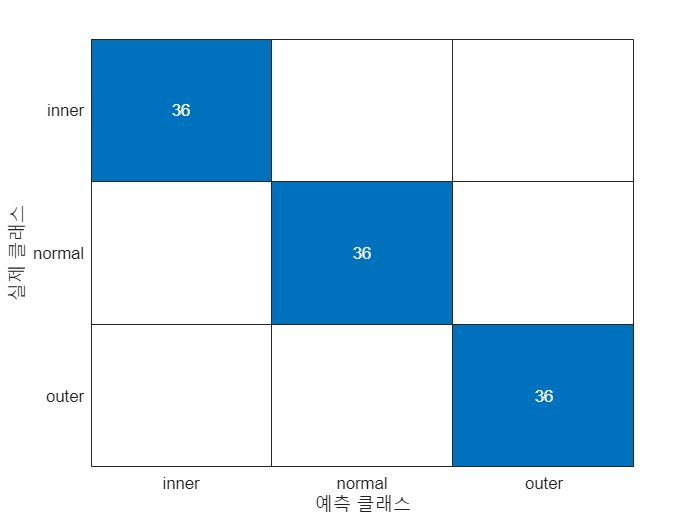

%%% YOUR CODE GOES HERE
figure
KNNResubCM = confusionchart(Ytest,pred);

**Plot  Test Results and  Misclassified Test data**

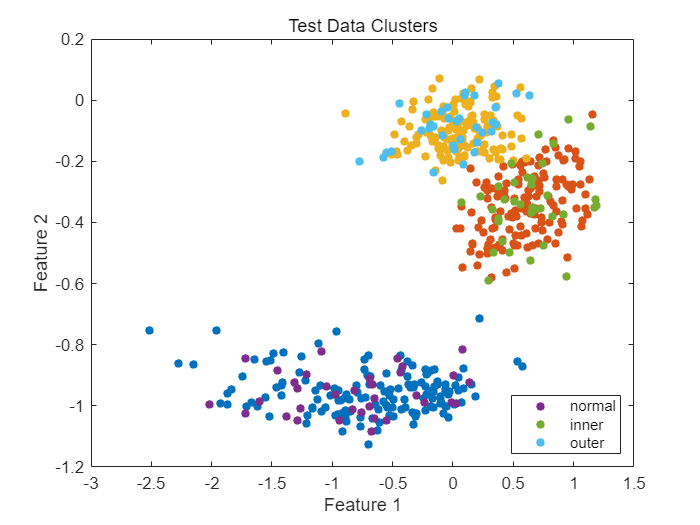

%%% YOUR CODE GOES HERE
bad = ~strcmp(pred,Ytest);

color = lines(6);               % Generate color values
figure
gscatter(X(:,1),X(:,2),Y, color(1:3,:))
hold on
gscatter(Xtest(:,1),Xtest(:,2),Ytest, color(4:6,:))
hold on;
plot(Xtest(bad,1), Xtest(bad,2), 'kx');
hold off;
title('Test Data Clusters')
xlabel('Feature 1')
ylabel('Feature 2')

#### Optimization of Fitted KNN

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |    0.016204 |    0.046001 |    0.016204 |    0.016204 |            1 |   seuclidean |        false |
|    2 | Accept |    0.025463 |    0.039783 |    0.016204 |    0.016572 |           23 |    chebychev |        false |
|    3 | Accept |     0.66667 |    0.042796 |    0.016204 |    0.029609 |          179 |      hamming |         true |
|    4 | Best   |    0.011574 |    0.045459 |    0.011574 |    0.011864 |            2 |    chebychev |         true |
|    5 | Accept |    0.011574 |    0.038971 |   

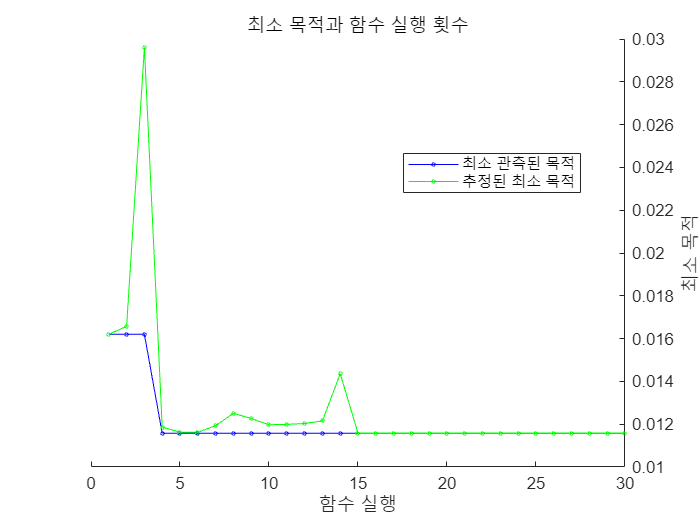

Mdl =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: {'inner'  'normal'  'outer'}
                       ScoreTransform: 'none'
                      NumObservations: 432
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'cityblock'
                         NumNeighbors: 2


  Properties, Methods


Mdl = fitcknn(X,Y,'OptimizeHyperparameters','auto',...
    'HyperparameterOptimizationOptions',...
    struct('AcquisitionFunctionName','expected-improvement-plus'))

 Compare performance of KNN with other classification methods